Robot1

L1(1) = Link('revolute','alpha',0,'a',0,'d',0.137,'offset',0,'modified');
L1(2) = Link('revolute','alpha',-pi/2,'a',0,'d',0,'offset',-pi/2,'qlim',[-pi/2 30*pi/180] ,'modified');
L1(3) = Link('revolute','alpha',0,'a',0.105,'d',0,'offset',0,'modified');
L1(4) = Link('revolute','alpha',0,'a',0.105,'d',0,'offset',0,'modified');

R_tool = [0  0  1;
         -1  0  0;
          0 -1  0];
P_tool = [0.11 0 0]';
T_4_tool = rt2tr(R_tool,P_tool);
R1 = SerialLink(L1,'name','phantom1');
R1.tool = T_4_tool;
R1

 
R1 = 
 
phantom1 (4 axis, RRRR, modDH, slowRNE)                                        
                                                                               
+---+-----------+-----------+-----------+-----------+-----------+              
| j |     theta |         d |         a |     alpha |    offset |              
+---+-----------+-----------+-----------+-----------+-----------+              
|  1|         q1|      0.137|          0|          0|          0|              
|  2|         q2|          0|          0|     -1.571|     -1.571|              
|  3|         q3|          0|      0.105|          0|          0|              
|  4|         q4|          0|      0.105|          0|          0|              
+---+-----------+-----------+-----------+-----------+-----------+              
                                                                               
grav =    0  base = 1  0  0  0   tool =   0           0           1        0.11
          0         0  1  0  0

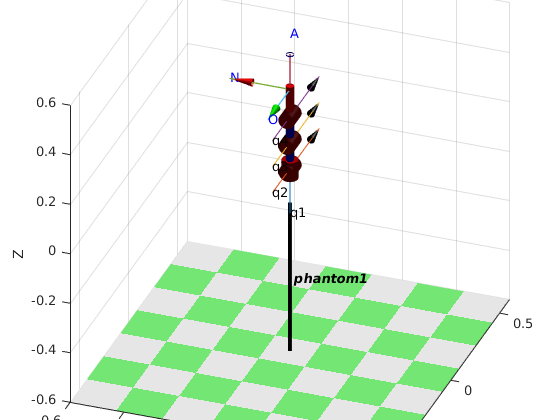




R1.plot([0 0 0 0],'noa','jvec','view',[20 30])

Robot2

L2(1) = Link('revolute','alpha',0,'a',0.5,'d',0.137,'offset',pi,'modified');
L2(2) = Link('revolute','alpha',-pi/2,'a',0,'d',0,'offset',-pi/2,'qlim',[-pi/2 30*pi/180] ,'modified');
L2(3) = Link('revolute','alpha',0,'a',0.105,'d',0,'offset',0,'modified');
L2(4) = Link('revolute','alpha',0,'a',0.105,'d',0,'offset',0,'modified');

R_tool = [0  0  1;
         -1  0  0;
          0 -1  0];
P_tool = [0.11 0 0]';
T_4_tool = rt2tr(R_tool,P_tool);
R2 = SerialLink(L2,'name','phantom2');
R2.tool = T_4_tool;
R2

 
R2 = 
 
phantom2 (4 axis, RRRR, modDH, slowRNE)                                        
                                                                               
+---+-----------+-----------+-----------+-----------+-----------+              
| j |     theta |         d |         a |     alpha |    offset |              
+---+-----------+-----------+-----------+-----------+-----------+              
|  1|         q1|      0.137|        0.5|          0|      3.142|              
|  2|         q2|          0|          0|     -1.571|     -1.571|              
|  3|         q3|          0|      0.105|          0|          0|              
|  4|         q4|          0|      0.105|          0|          0|              
+---+-----------+-----------+-----------+-----------+-----------+              
                                                                               
grav =    0  base = 1  0  0  0   tool =   0           0           1        0.11
          0         0  1  0  0

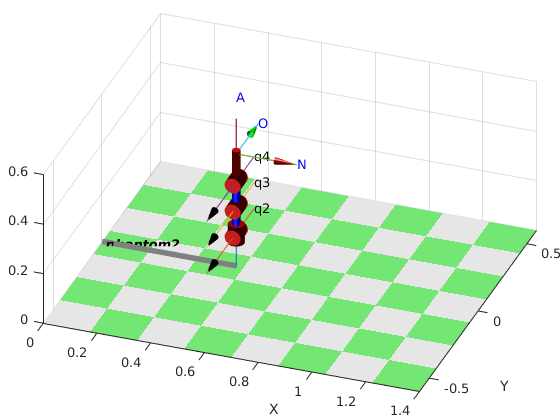




R2.plot([0 0 0 0],'workspace',[0 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])

pic and place calculos

Primer punto

qi_1 =[0 0 0.5 0.2 0 0];

Punto_aprox = [1  0  0  0.1;
               0 -1  0  0;
               0  0 -1  0.2;
               0  0  0  1];

qi_2 = [ikunc(R1,Punto_aprox,qi_1(1:4)) 0 0] %llamamos la función

qi_2 =     0.0000    0.2115    0.6252    2.3049         0         0


fkine(R1,qi_2(1:4))

ans =     1.0000    0.0000    0.0000    0.1000
    0.0000   -1.0000    0.0000    0.0000
    0.0000   -0.0000   -1.0000    0.2000
         0         0         0    1.0000


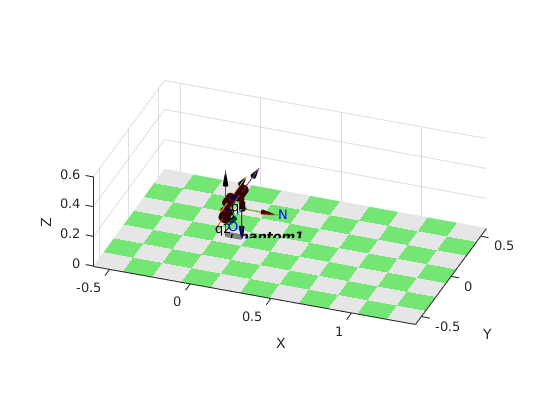

R1.plot(qi_2(1:4),'workspace',[-0.5 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])

Segundo punto

entrada_x=0.1;
entrada_y=0.1;
x = 0+entrada_x;
y = 0.1+entrada_y;

Punto_aprox = [1  0  0  x;
               0 -1  0  y;
               0  0 -1  0.2;
               0  0  0  1];
qi_3 = [ikunc(R1,Punto_aprox,qi_2(1:4)) 0 0] %llamamos la función

qi_3 =     0.6649    0.8215    0.0000    2.1589         0         0


R1.plot(qi_3(1:4),'workspace',[-.05 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])

Tercer punto 



Punto_aprox = [1  0  0  x;
               0 -1  0  y;
               0  0 -1  0.1;
               0  0  0  1];
qi_4 = [ikunc(R1,Punto_aprox,qi_3(1:4)) 0 0] %llamamos la función

qi_4 =     0.7084    1.2261    0.0000    1.8894         0         0


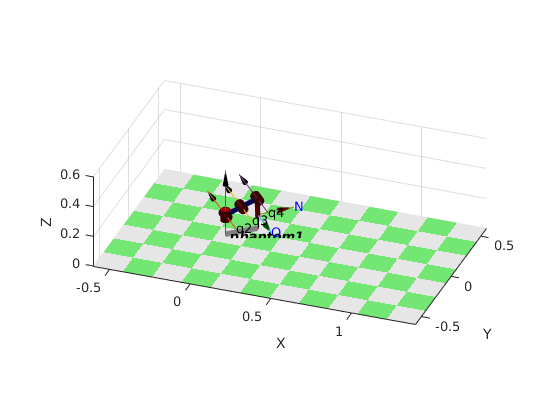

R1.plot(qi_4(1:4),'workspace',[-0.5 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])

qi_5 = [qi_3(1:4) 0.016 0.016];

Punto_aprox = [1  0  0  x;
               0 -1  0  y;
               0  0 -1  0.15;
               0  0  0  1];
qi_6 = [ikunc(R1,Punto_aprox,qi_5(1:4)) 0.016 0.016] %llamamos la función

qi_6 =     0.6891    1.0097   -0.0000    2.0476    0.0160    0.0160


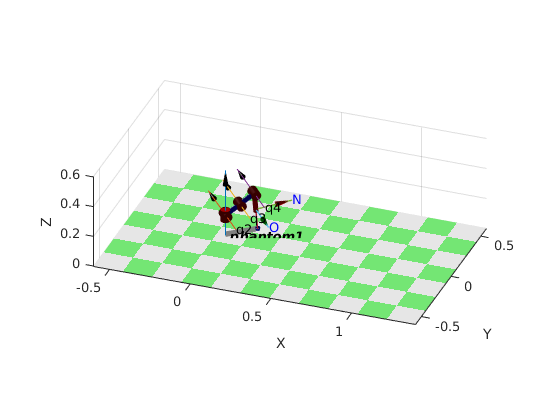

R1.plot(qi_6(1:4),'workspace',[-0.5 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])

Punto_aprox = [1  0  0  0.15;
               0 -1  0 -0.15;
               0  0 -1  0.15;
               0  0  0  1];
qi_6 = [ikunc(R1,Punto_aprox,qi_5(1:4)) 0.016 0.016] %llamamos la función

qi_6 =    -0.4717    1.0060   -0.0000    2.0616    0.0160    0.0160


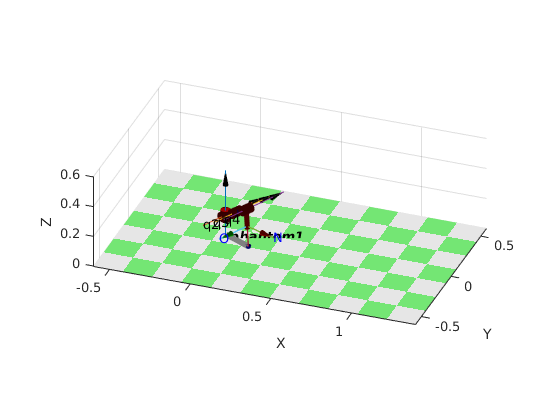

R1.plot(qi_6(1:4),'workspace',[-0.5 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])

Punto_aprox = [1  0  0  0.2;
               0 -1  0 -0.2;
               0  0 -1  0.06;
               0  0  0  1]

Punto_aprox =     1.0000         0         0    0.2000
         0   -1.0000         0   -0.2000
         0         0   -1.0000    0.0600
         0         0         0    1.0000


qi_6 = [ikunc(R1,Punto_aprox,qi_5(1:4)) 0.016 0.016] %llamamos la función

qi_6 =    -0.5661    1.4503    0.0000    1.4871    0.0160    0.0160


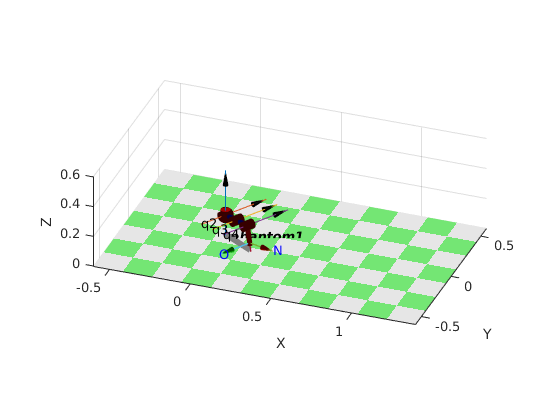

R1.plot(qi_6(1:4),'workspace',[-0.5 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])

qi_7 = [qi_6(1:4) 0.016 0.016];

rosinit

The value of the ROS_MASTER_URI environment variable, http://localhost:11311, will be used to connect to the ROS master.
Initializing global node /matlab_global_node_53733 with NodeURI http://julian-XPS-8700:37795/


phantompos = rospublisher('/robot_1/phantom_position_controller/command');
message = rosmessage(phantompos)

message =   ROS Float64MultiArray message with properties:

    MessageType: 'std_msgs/Float64MultiArray'
         Layout: [1×1 MultiArrayLayout]
           Data: [0×1 double]

  Use showdetails to show the contents of the message


positionreal = rossubscriber('/robot_1/joint_states');
pause(1);
message.Data = qi_1;
send(phantompos,message);
states = receive(positionreal,1).Position;
states = round([states(3:6)' states(1:2)'],2)

states =          0         0    0.5000    0.2000         0         0


while ( isequal( states, round(qi_1,2) ) == 0)
    states = receive(positionreal,1).Position;
    states = round([states(3:6)' states(1:2)'],2)
end

message.Data = qi_2;
send(phantompos,message);
states = receive(positionreal,1).Position;
states = round([states(3:6)' states(1:2)'],2)

states =          0    0.0100    0.5100    0.2100         0         0


while ( isequal( states, round(qi_2,2) ) == 0 )
    states = receive(positionreal,1).Position;
    states = round([states(3:6)' states(1:2)'],2)
end

states =          0    0.0200    0.5200    0.2200         0         0


states =          0    0.0300    0.5300    0.2300         0         0


states =          0    0.0400    0.5400    0.2400         0         0


states =          0    0.0500    0.5500    0.2500         0         0


states =          0    0.0600    0.5600    0.2600         0         0


states =          0    0.0700    0.5700    0.2700         0         0


states =          0    0.0800    0.5800    0.2800         0         0


states =          0    0.0900    0.5900    0.2900         0         0


states =          0    0.1000    0.6000    0.3000         0         0


states =          0    0.1100    0.6100    0.3100         0         0


states =          0    0.1200    0.6200    0.3200         0         0


states =          0    0.2100    0.6300    1.0300         0         0


states =          0    0.2100    0.6300    1.7400         0         0


states =          0    0.2100    0.6300    2.3000         0         0



message.Data = qi_3 ;
send(phantompos,message);
states = receive(positionreal,1).Position;
states = round([states(3:6)' states(1:2)'],2)

states =     0.6600    0.8200         0    2.1600         0         0


while ( isequal( states, round(qi_3,2) ) == 0 )
    states = receive(positionreal,1).Position;
    states = round([states(3:6)' states(1:2)'],2)
end


message.Data = qi_4;
send(phantompos,message);
states = receive(positionreal,1).Position;
states = round([states(3:6)' states(1:2)'],2)

states =     0.7100    1.2300         0    1.8900         0         0


while ( isequal( states, round(qi_4,2) ) == 0 )
    states = receive(positionreal,1).Position;
    states = round([states(3:6)' states(1:2)'],2)
end

message.Data = qi_5;
send(phantompos,message);
states = receive(positionreal,1).Position;
states = round([states(3:6)' states(1:2)'],2)

states =     0.6600    0.8200         0    2.1600    0.0200    0.0200


while ( isequal( states, round(qi_5,2) ) == 0 )
    states = receive(positionreal,1).Position;
    states = round([states(3:6)' states(1:2)'],2)
end

message.Data = qi_6;
send(phantompos,message);
states = receive(positionreal,1).Position;
states = round([states(3:6)' states(1:2)'],2)

states =     0.0800    1.4000         0    1.5800    0.0200    0.0200


while ( isequal( states, round(qi_6,2) ) == 0 )
    states = receive(positionreal,1).Position;
    states = round([states(3:6)' states(1:2)'],2)
end

states =    -0.4800    1.4500         0    1.4900    0.0200    0.0200


states =    -0.5700    1.4500         0    1.4900    0.0200    0.0200



message.Data = qi_7;
send(phantompos,message);
states = receive(positionreal,1).Position;
states = round([states(3:6)' states(1:2)'],2)

states =    -0.5700    1.4500         0    1.4900    0.0200    0.0200


while ( isequal( states, round(qi_7,2) ) == 0 )
    states = receive(positionreal,1).Position;
    states = round([states(3:6)' states(1:2)'],2)
end

message.Data = qi_1;
send(phantompos,message);
states = receive(positionreal,1).Position;
states = round([states(3:6)' states(1:2)'],2)

states =    -0.1400    1.0300    0.4200    1.0700         0         0


states =          0    0.5600    0.5000    0.6000         0         0


states =          0    0.1300    0.5000    0.2000         0         0


states =          0    0.1100    0.5000    0.2000         0         0


states =          0    0.1000    0.5000    0.2000         0         0


states =          0    0.0900    0.5000    0.2000         0         0


states =          0         0    0.5000    0.2000         0         0


while ( isequal( states, round(qi_1,2) ) == 0 )
    states = receive(positionreal,1).Position;
    states = round([states(3:6)' states(1:2)'],2)
end




rosshutdown

Shutting down global node /matlab_global_node_53733 with NodeURI http://julian-XPS-8700:37795/
